[datafile, path] = uigetfile();
data = load(strcat(path, datafile));

Error using load
File name is empty.

dtype = "i1";

date = "2014-04-01";
dataDir = 'Z:\4A\WindTurbineMonitoring\data\'; %uigetdir; %gets directory
allFiles = dir(fullfile(dataDir,date + "*"));
old_data = load(strcat(dataDir, allFiles(1).name));
for i = 2:length(allFiles)
    data = old_data;
    data = load(strcat(dataDir, allFiles(i).name));
    f = fieldnames(data);
    for j = 1:length(f)
        structB.(f{j}) = structA.(f{j})
    end
    data = structB;
end

Reference to non-existent field 'i1'.

%nsamples = size(data.gfjf.rawData);
%t0 = data.i1.timeStamp;
%fs = data.i1.fs;
%ts = 1/fs;

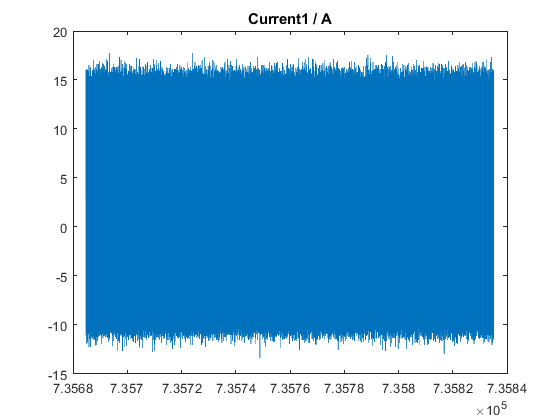


%time_axis = linspace(t0, t0 + ts * nsamples, nsamples);
%plot(time_axis, data.i1.rawData)
%title(data.i1.sensorName + " / " + data.i1.unit)

%xlabel("Time / s")
%ylabel(data.i1.unit)


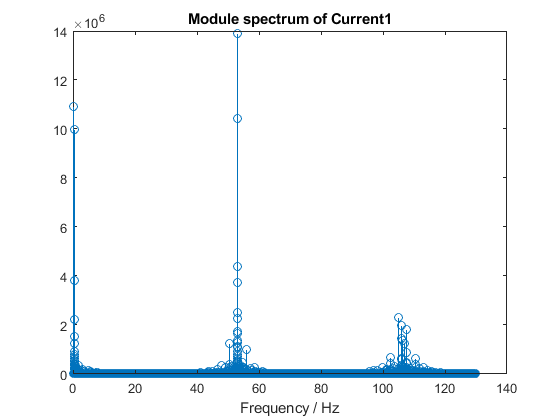

%T = time_axis(end)-time_axis(1);
%freq_axis = linspace(0, 1/T * fs/2, nsamples/2);
%spectr = abs(fft(data.i1.rawData));
%stem(freq_axis, spectr(1:(nsamples/2)))
%title("Module spectrum of " + data.i1.sensorName)
%xlabel("Frequency / Hz")

%structA = data1;
%structB = data2;


structB = struct with fields:
     i1: [1×1 struct]
    hss: [1×1 struct]
